7-1

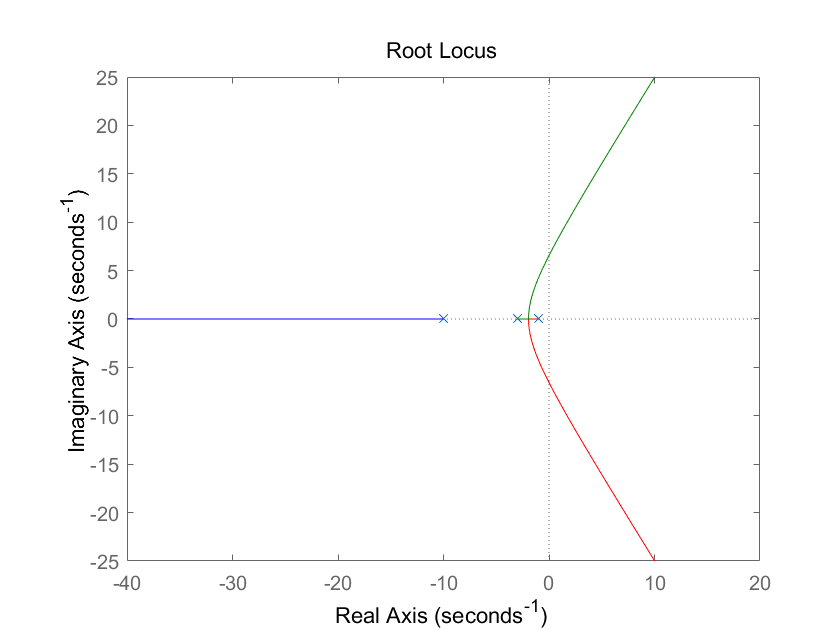

%a)
sys = tf([10], [1, 14, 43, 30]);
rlocus(sys)

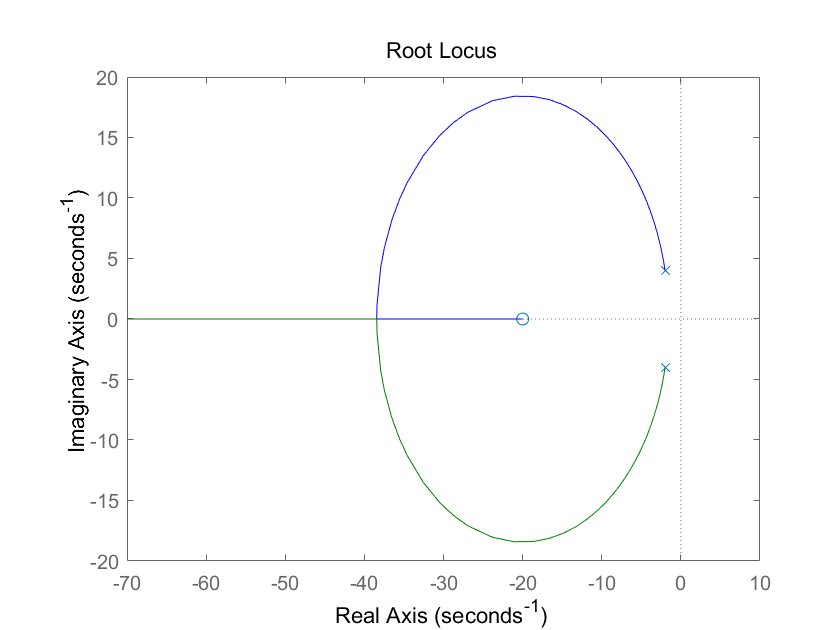


%b)
sys = tf([1, 20], [1, 4, 20]);
rlocus(sys)

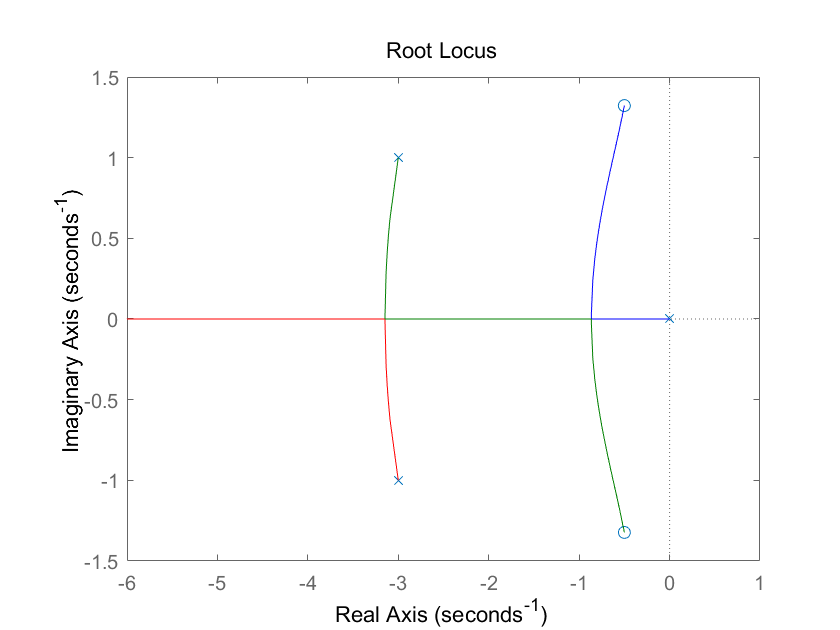


%c)
sys = tf([1, 1, 2], [1, 6, 10, 0]);
rlocus(sys)

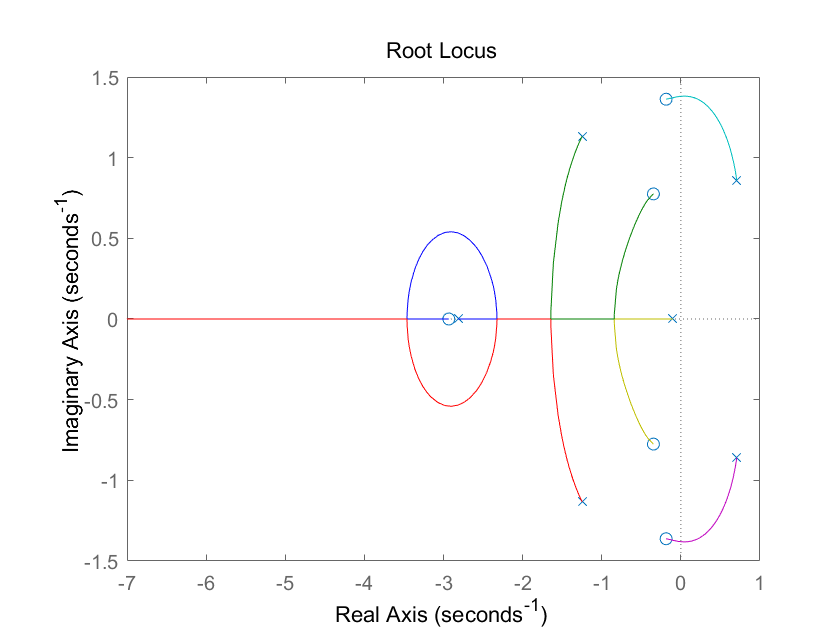


%d)
sys = tf([1, 4, 6, 10, 6, 4], [1, 4, 4, 1, 1, 10, 1]);
rlocus(sys)

7-2

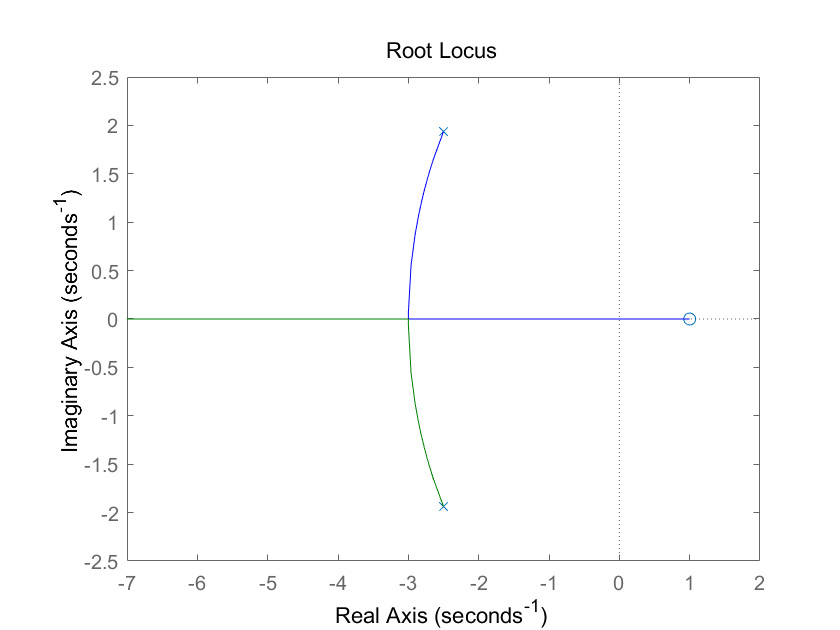

% p(s-1)/(s^2+5s+10)
sys = tf([1 -1], [1 5 10]);
rlocus(sys)

%rlocfind(sys)

通过rlocfind得到sys在零点处，p值为10.03左右，所以p取值为0到10可保证闭环系统稳定。

7-3

先根据要求确定极点的可行域，对于原本的三阶系统，其根轨迹向右半平面无限延伸，为了稳定和指标要求，尝试通过增加合适的开环零点，使根轨迹向左弯曲。尝试微分控制器 K(s+z）

%z=8
sys = tf([10 80], [1 15 50 0])

sys =
 
       10 s + 80
  -------------------
  s^3 + 15 s^2 + 50 s
 
Continuous-time transfer function.



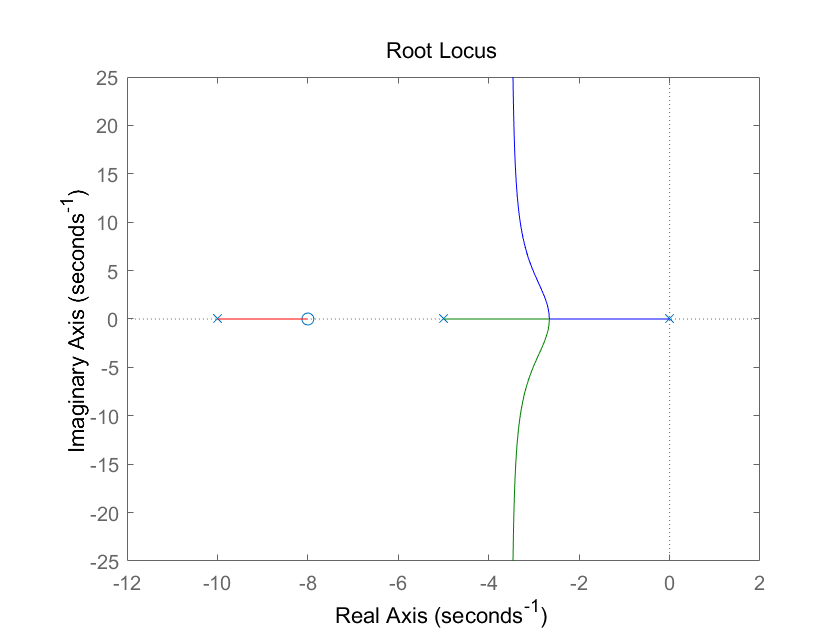

rlocus(sys)

%rlocfind(sys)
%K = 1.28

但是此时K_v<100，不满足要求，所以尝试加入小极点-0.01和小零点-0.0001

sys1 = tf([10], [1 15 50 0]);
sys2 = tf(conv([1 8], [1 0.01]), [1 0.0001]);
sys = series(sys1, sys2)

sys =
 
       10 s^2 + 80.1 s + 0.8
  -------------------------------
  s^4 + 15 s^3 + 50 s^2 + 0.005 s
 
Continuous-time transfer function.



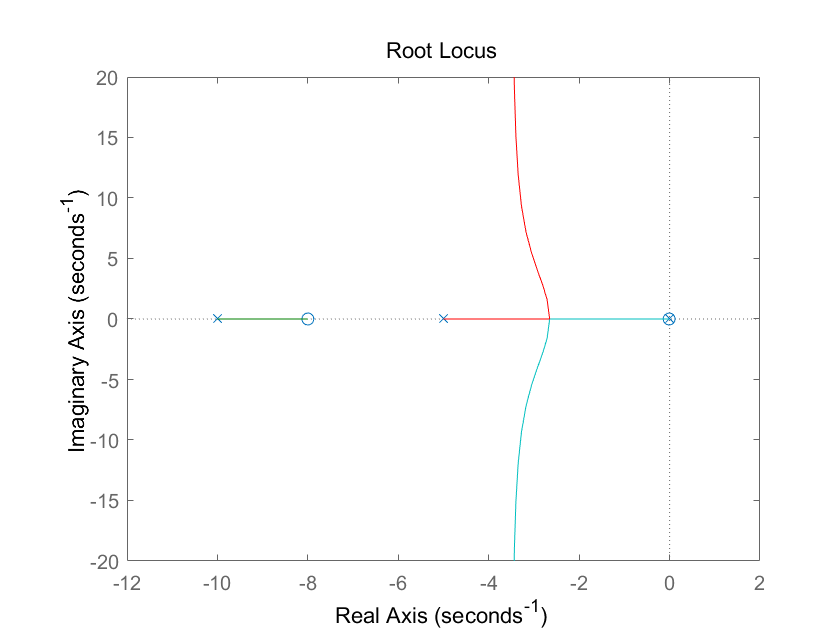

rlocus(sys)

%rlocfind(sys)

K=1.04，此时满足K_v>=100

(b)

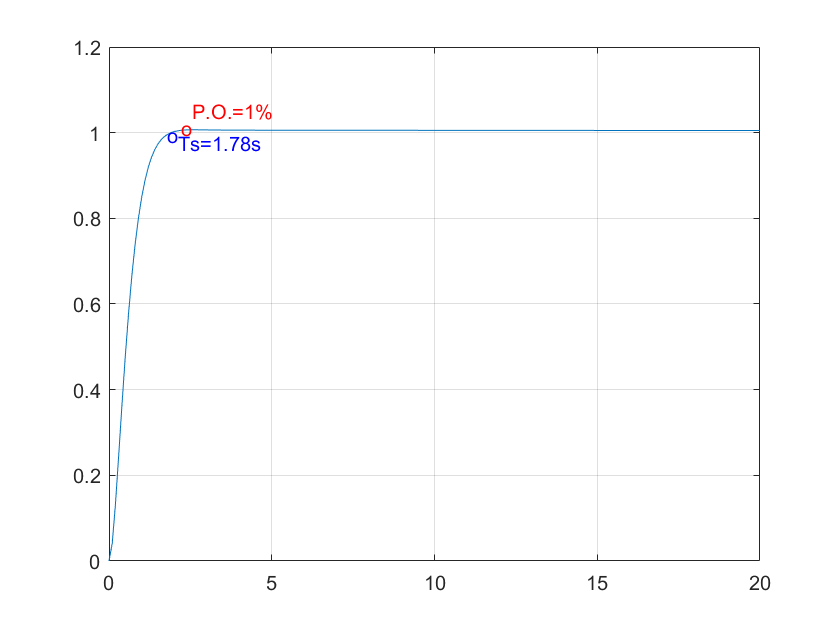

sys1 = tf([10], [1 15 50 0]);
sys2 = tf(1.04 * conv([1 8], [1 0.01]), [1 0.0001]);
sys = series(sys1, sys2);
sys = feedback(sys,1);
t = 0:0.1:20;
%step(sys, t)
y = step(sys, t);
plot(t, y), grid
text(2.22, 1.05,['  P.O.=1%'], 'color', 'r')
text(2.22, 1.01,'o', 'color', 'r')
text(1.78, 0.975,['  Ts=1.78s'], 'color', 'b')
text(1.78, 0.995,'o', 'color', 'b')

(c)

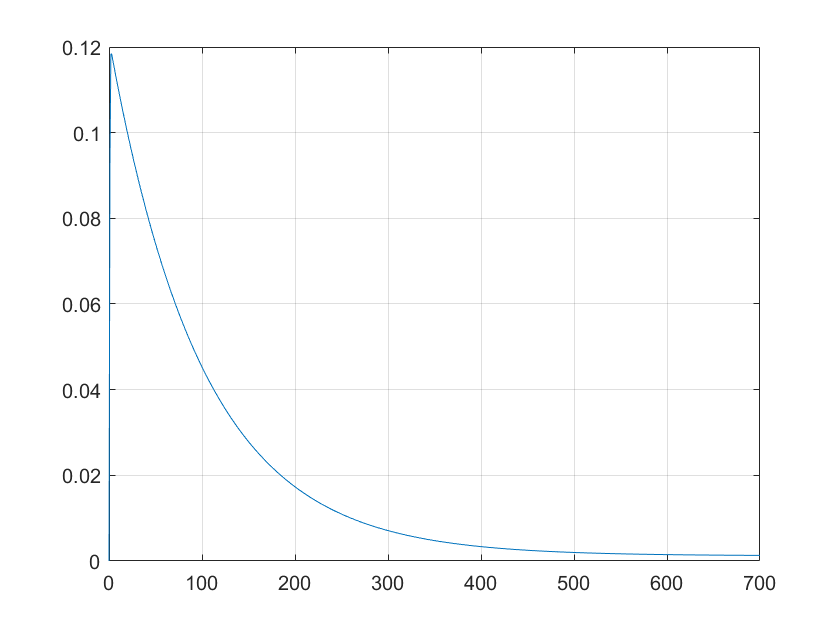

sys1 = tf([10], [1 15 50 0]);
sys2 = tf(1.04 * conv([1 8], [1 0.01]), [1 0.0001]);
systd=feedback(sys1,sys2);
t = 0:1:700;
y = step(systd, t);
plot(t,y), grid

7-4

(a)

根据指标，极点横坐标小于-4/10(2%准则下），同时阻尼系数小于0.6， 与原点的连线与负半轴角度小于arccos0.6=53.8

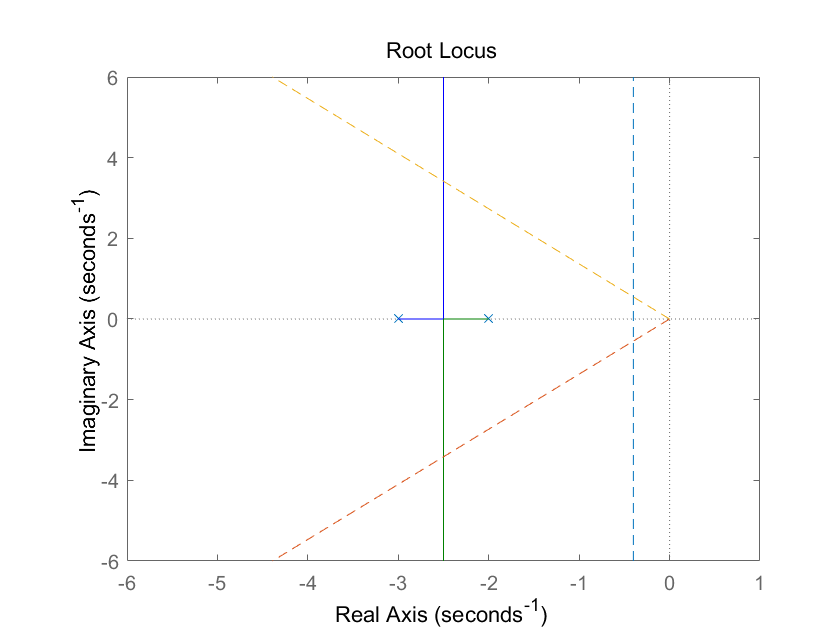

sys1 = tf([1], [1 5 6]);
sys2 = tf([1], [1]);
sys_a = series(sys1, sys2);
rlocus(sys_a)
hold on
plot([-0.4,-0.4],[-100,100],'--',...
[0,-10],[0,-10*tan(53.8*pi/180)],'--',...
[0,-10],[0,10*tan(53.8*pi/180)],'--')
hold off
axis([-6,1,-6,6])


%rlocfind(sys_a)

K=10.88

(b)

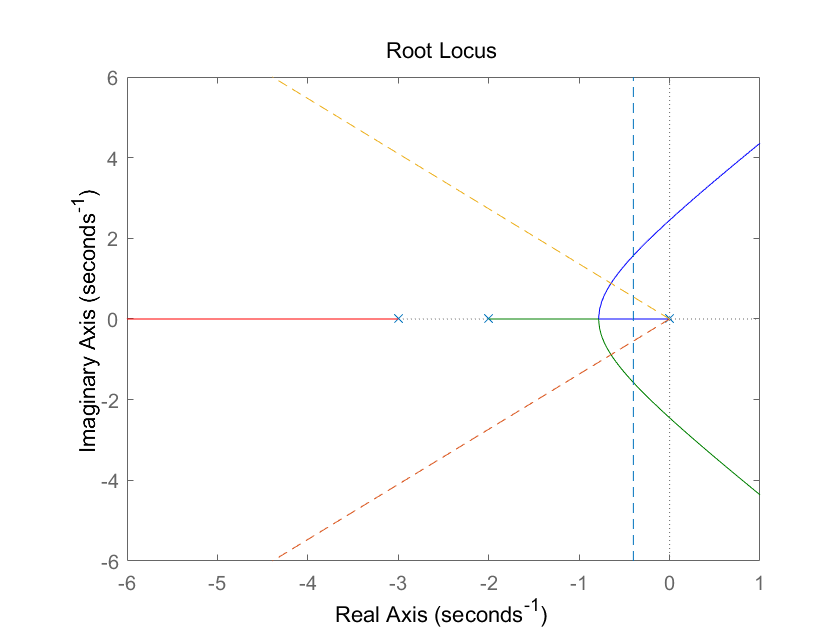

sys1 = tf([1], [1 5 6]);
sys2 = tf([1], [1 0]);
sys_b = series(sys1, sys2);
rlocus(sys_b)
hold on
plot([-0.4,-0.4],[-100,100],'--',...
[0,-10],[0,-10*tan(53.8*pi/180)],'--',...
[0,-10],[0,10*tan(53.8*pi/180)],'--')
hold off
axis([-6,1,-6,6])


%rlocfind(sys_b)

K=4.694

(c)

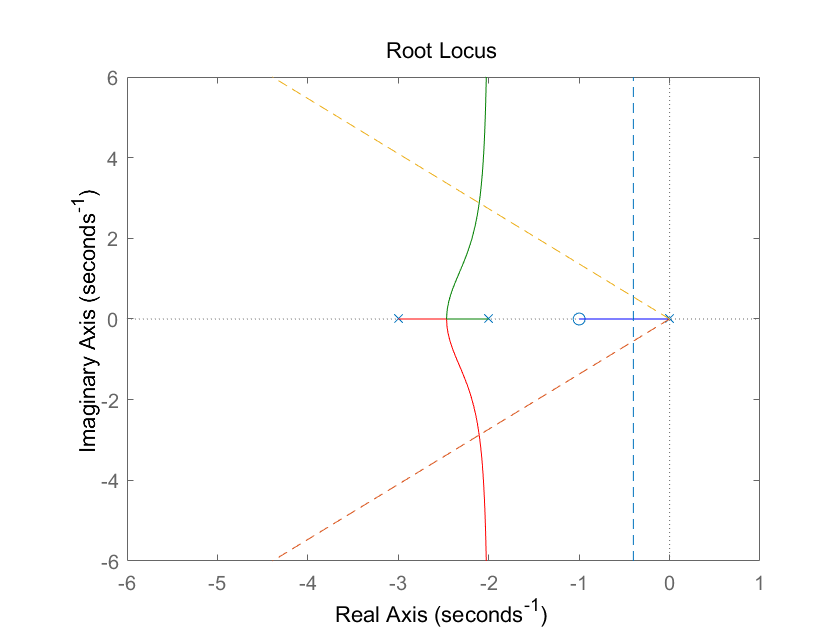

sys1 = tf([1], [1 5 6]);
sys2 = tf([1 1], [1 0]);
sys_c = series(sys1, sys2);
rlocus(sys_c)
hold on
plot([-0.4,-0.4],[-100,100],'--',...
[0,-10],[0,-10*tan(53.8*pi/180)],'--',...
[0,-10],[0,10*tan(53.8*pi/180)],'--')
hold off
axis([-6,1,-6,6])


%rlocfind(sys_c)

K=9.658

(d)

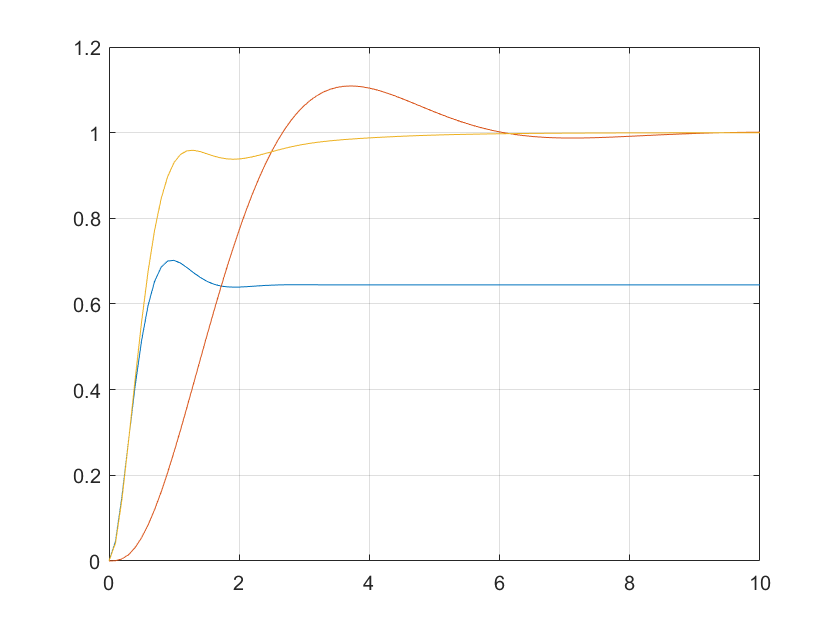

figure
t=0:0.1:10;
sys1 = feedback(10.88*sys_a, 1);
y1 = step(sys1, t);
sys2 = feedback(4.694*sys_b, 1);
y2 = step(sys2, t);
sys3 = feedback(9.658*sys_c, 1);
y3 = step(sys3, t);
plot(t, y1, t, y2, t, y3), grid

(e)

比例控制器的瞬态响应快，但稳态误差大于0.

积分控制器稳态误差为0，但存在超调，同时响应慢。

比例积分控制器优于上述两种控制器，稳态误差为0，且不存在超调，响应快。

7-5

（Kd/J） *(s+5/s^2)

sys = tf([1 5], [1 0 0])

sys =
 
  s + 5
  -----
   s^2
 
Continuous-time transfer function.



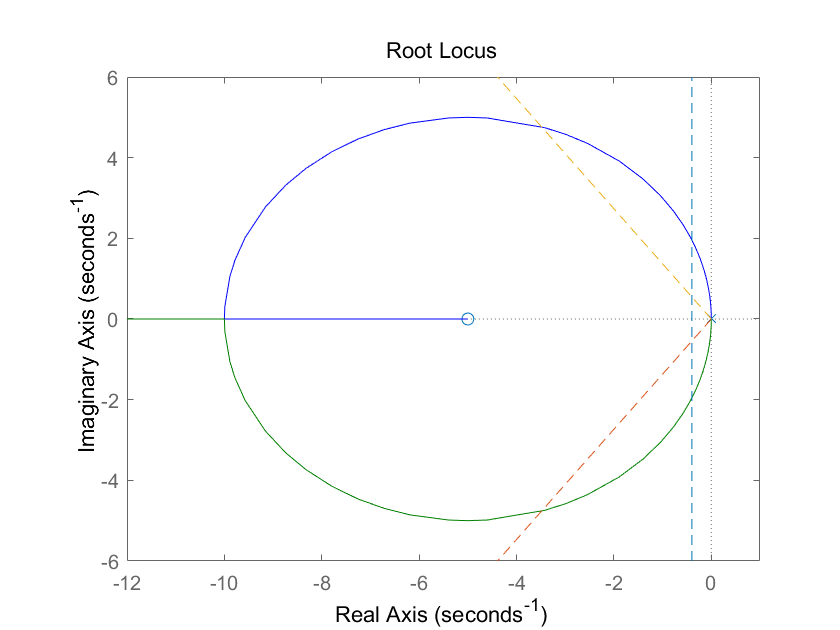

rlocus(sys)
hold on
plot([-0.4,-0.4],[-100,100],'--',...
[0,-10],[0,-10*tan(53.8*pi/180)],'--',...
[0,-10],[0,10*tan(53.8*pi/180)],'--')
hold off
axis([-12,1,-6,6])

%rlocfind(sys)

Kd/J >= 7.2; Kp/J>=36时系统稳定

7-6

代入解得：K=5.2

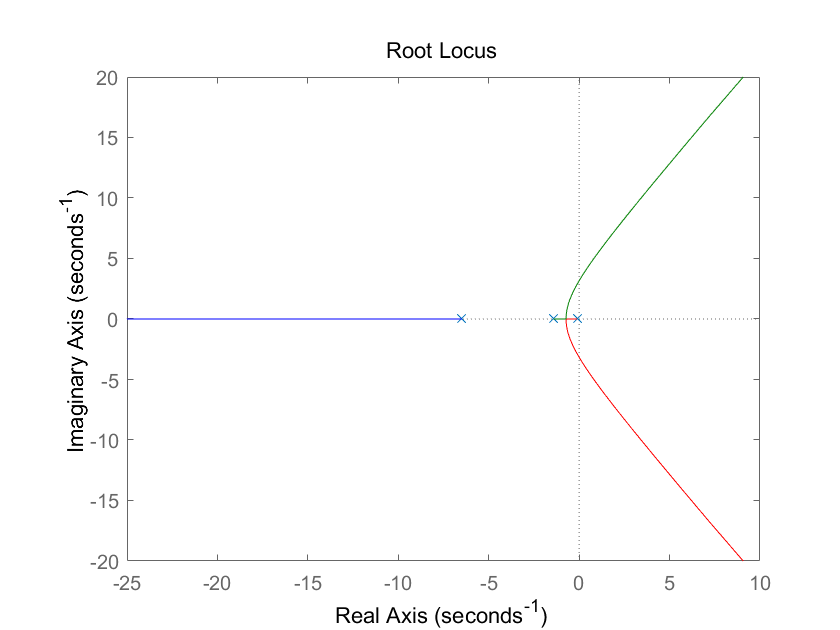

sys = tf([1], [1 8 10 1]);
rlocus(sys)